# ELEX7620 Lab 7

Name:  Ryan Wong, A00958475, and set:T

Objective:  To will implement a FIR bandpass filter (BPF) on the FM4‐176L‐S6E2CC‐ETH platform, where the filter is designed by using the windowing technique

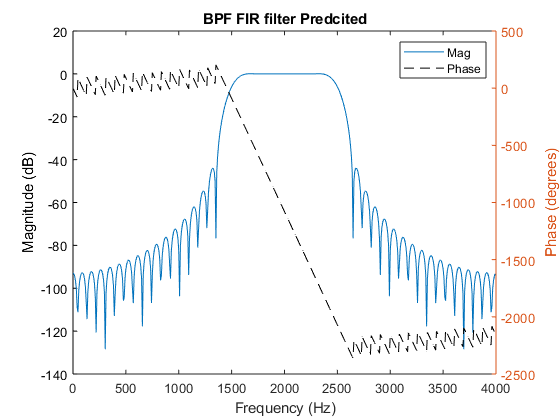

n = 88;                                         %Order
fs = 8000;                                      %Sampling Frequency
fc1 = 1500;                                        %Cut-off Frequency2
fc2 = 2500;                                     %Cut-off Frequency2
b = fir1(n, [2*(fc1/fs) 2*(fc2/fs)] , 'bandpass', hanning(n+1));   %numerator coefficients
[h, f] = freqz(b, 1,512, fs);

freq = f;
mag = 20*log10(abs(h(:,:)));
phase = unwrap(angle(h(:,:))) * 57.2958; 

figure(1)
clf
plot(freq,mag)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('BPF FIR filter Predcited')
hold on
yyaxis right
plot(freq,phase(:,:),'k--')
ylabel('Phase (degrees)')
legend('Mag','Phase')
hold off

Gain at 2000 Hz = 0dB

Gain at passband edge (1500): -6dB

Gain at passband edge (2500): -6dB

## FIR Filter Calculations

## 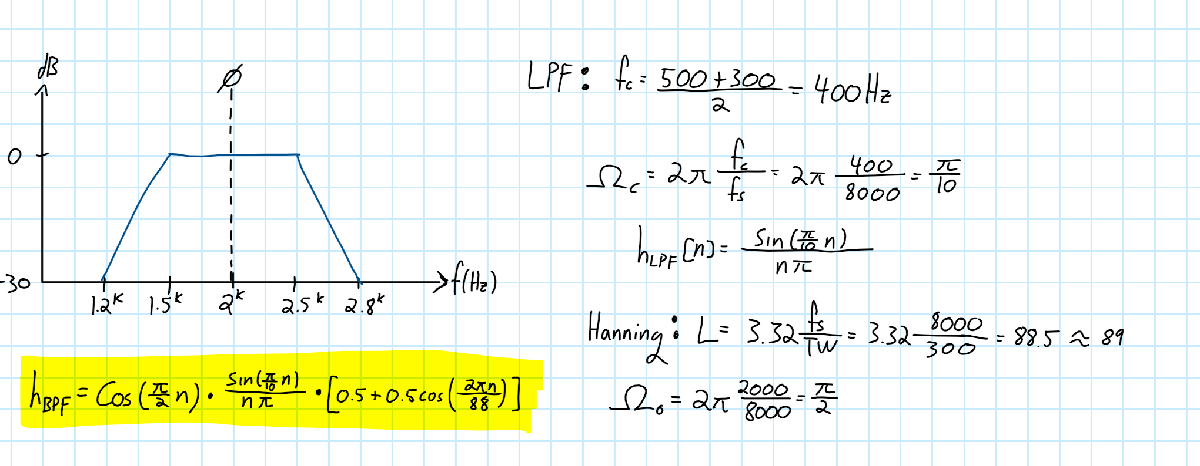

## Export Coefficients

%fir_coeffs(b)

## Measurements

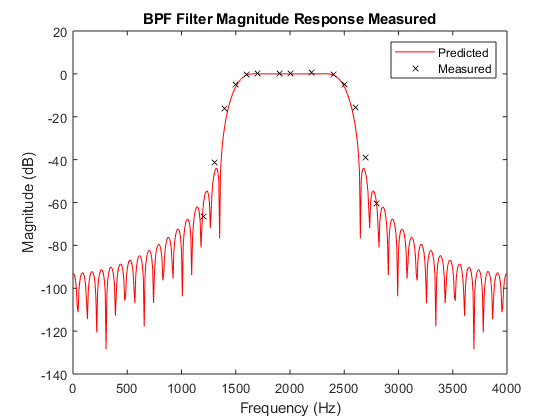

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[2000, 1.10]
            [1900, 1.10]
            [1700, 1.11]
            [1600, 1.04]
            [1500, 0.6]
            [1400, 0.170]
            [1300, 9e-3]
            [1200, 5e-4]
            [2200, 1.13]
            [2400, 1.04]
            [2600, 0.180]
            [2500, 0.620]
            [2700, 0.012]
            [2800, 1e-3]

            %cant really read anything in the stop band 
            %guess that means its stopped
           ];

       
           
%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 1.07;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);


figure(2)
clf
plot(freq,mag,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('BPF Filter Magnitude Response Measured')
legend('Predicted', 'Measured')

## Further Refinement - 5db of Margin

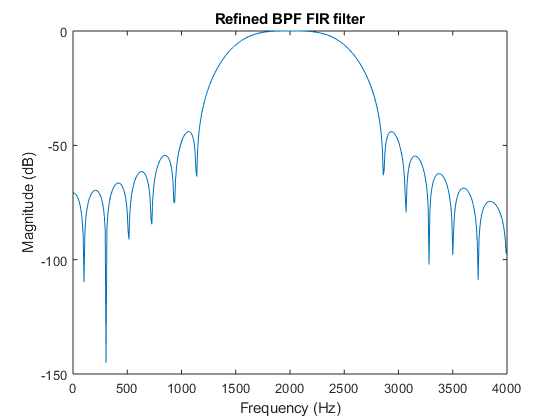

n = 35;                                         %Order
fs = 8000;                                      %Sampling Frequency
fc1 = 1500;                                        %Cut-off Frequency2
fc2 = 2500;                                     %Cut-off Frequency2
b1 = fir1(n, [2*(fc1/fs) 2*(fc2/fs)] , 'bandpass', hanning(n+1));   %numerator coefficients
[h, f] = freqz(b1, 1,512, fs);

freq = f;
mag = 20*log10(abs(h(:,:)));
phase = unwrap(angle(h(:,:))) * 57.2958; 

figure(1)
clf
plot(freq,mag)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Refined BPF FIR filter')


%fir_coeffs(b1)

## Measurements Refined BPF

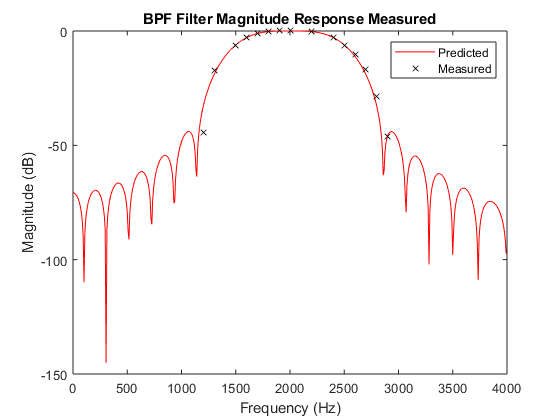

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[2000, 1.07]
            [2200, 1.03]
            [2400, 0.776]
            [2500, 0.516]
            [2600, 0.328]
            [2700, 0.156]
            [2800, 0.040]
            [2900, 0.0052]
            [1900, 1.07]
            [1800, 1.04]
            [1700, 0.944]
            [1600, 0.776]
            [1500, 0.52]
            [1300, 0.148]
      



            %cant really read anything in the stop band 
            %guess that means its stopped
           ];

       
           
%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 1.07;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);


figure(1)
clf
plot(freq,mag,'r-',meas_freq,meas_mag_dB,'kx')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('BPF Filter Magnitude Response Measured')
legend('Predicted', 'Measured')

Stopband attenuation (1200): -32.34dB

Stopband attenuation (1200): -33.96dB

## C code for FM4-176L-S6E2CC-ETH